### Single Particle Model with Thermal (SPMT) using Orthogonal Chebyshev Collocation Method

clear;
clc;
close all;
addpath(genpath('dmsuite'));
addpath(genpath('model_parameters'));

% get lithium ion cell data
data = get_modelDataLGM50;

% Generate collocation nodes
N = 15; % N+1 is chebyshev nodes used to discretize solid diffusion equation
M = 2*N; % for discretizing 
nodes.xm = cos(pi*(0:M)/M)'; % [-R,R] -> [-1,1]
nodes.xr = nodes.xm(1:N+1); % [0,R] -> [0,1]

% Generate collocation nodes for electrolyte
M_a = 30; % M+1 chebyshev nodes for negative electrode (Anode)
K_s = 20; % K+1 chebyshev nodes for separator
Q_c = 30; % Q+1 chebyshev nodes for positive electrode (Cathode)
nodes.xm_a = cos(pi*(0:M_a)/M_a)'; % [-1,1] Anode
nodes.xk_s = cos(pi*(0:K_s)/K_s)'; % [-1,1] Separator
nodes.xq_c = cos(pi*(0:Q_c)/Q_c)'; % [-1,1] Cathode

spm_matrices.N = N;
spm_matrices.M_a = M_a;
spm_matrices.K_s = K_s;
spm_matrices.Q_c = Q_c;

% Calculate Clenshaw-Curtis quadrature weights for calculating integrals of
% positive and negative electrode electrolyte concentration
[~,wm_a] = clencurt(M_a);
spm_matrices.wm_a = wm_a;

[~,wq_c] = clencurt(Q_c);
spm_matrices.wq_c = wq_c;

% Generate A,B,C,D state matrices for du/dt and concentration calculation
% Step 1: Create Differentiation matrix for second order
[~, D] = chebdif(M+1,2); % Create differentiation matrix for 1st and 2nd order
D1 = squeeze(D(1,:,1)); % [1,M+1] Access only first order differentiation matrix where r=1
D2 = squeeze(D(1:N,:,2)); % [N,M+1] Access 2nd order differentiation matrix for r=[1, 0]

% Step 2: Create Dn_delta matrix for convenience
P = fliplr(eye(N)); % Backward identity matrix
DN2 = D2(:,1:N) - D2(:,N+2:M+1)*P; % for 2nd order
DN1 = D1(1,1:N) - D1(1,N+2:M+1)*P; % for 1st order

% Step 3: Create A, B, C, D matrix for du/dt solid diffusion eqn
A = DN2(2:N,2:N) + (DN2(2:N,1)*DN1(1,2:N))/(1-DN1(1,1));
B = DN2(2:N,1)/(1-DN1(1,1));
C = DN1(1,2:N)/(1-DN1(1,1));
D = 1/(1-DN1(1,1));

% Step 4: Create An, Bn, Cn, Dn & Ap, Bp, Cp, Dp for each electrode particle using general A, B,
% C, D matrix
% Create for anode 
spm_matrices.An = (1/data.Rs1^2)*A;
spm_matrices.Bn = B;
spm_matrices.Cn = vertcat(C/data.Rs1, diag(1./(nodes.xr(2:N).*data.Rs1)));
spm_matrices.Dn = vertcat(data.Rs1*D, zeros(N-1,1));

% Create for cathode
spm_matrices.Ap = (1/data.Rs3^2)*A;
spm_matrices.Bp = B;
spm_matrices.Cp = vertcat(C/data.Rs3, diag(1./(nodes.xr(2:N).*data.Rs3)));
spm_matrices.Dp = vertcat(data.Rs3*D, zeros(N-1,1));

% Calculate Clenshaw-Curtis quadrature weights for calculating integrals
[~,wm] = clencurt(M);
wn = horzcat((wm(1:N) + wm(N+2:M+1)*P), wm(N+1));
spm_matrices.wn = wn;

% Generate D"_321 and D'_321 matrices
[~,Dm] = chebdif(M_a+1,2); % Differentiation matrix for Anode
Dm1 = squeeze(Dm(:,:,1)); % First order differentiation matrix Anode
Dm2 = squeeze(Dm(:,:,2)); % Second order differentiation matrix Anode

[~,Dk] = chebdif(K_s+1,2); % Differentiation matrix for Separator
Dk1 = squeeze(Dk(:,:,1)); % 1st order differentiation matrix Separator
Dk2 = squeeze(Dk(:,:,2)); % 2nd order differentiation matrix Separator

[~,Dq] = chebdif(Q_c+1,2); % Differentiation matrix for Cathode
Dq1 = squeeze(Dq(:,:,1)); % 1st order differentiation matrix Cathode
Dq2 = squeeze(Dq(:,:,2)); % 2nd order differentiation matrix Cathode

% Create M=A^(-1)*B matrix using Boundary Condition of Electrolyte
A_e = zeros(4,4);
B_e = zeros(4,(M_a+K_s+Q_c-3));

Dq1_scaled = (2*data.eps3e^(data.brug)/data.thick3).*Dq1;
Dk1_scaled = (2*data.eps2e^(data.brug)/data.thick2).*Dk1;
Dm1_scaled = (2*data.eps1e^(data.brug)/data.thick1).*Dm1;

A_e(1,1) = Dq1_scaled(1,1); A_e(1,2) = Dq1_scaled(1,Q_c+1);
A_e(2,1) = Dq1_scaled(Q_c+1,1); A_e(2,2) = Dq1_scaled(Q_c+1,Q_c+1) - Dk1_scaled(1,1); A_e(2,3) = -Dk1_scaled(1,K_s+1);
A_e(3,2) = Dk1_scaled(K_s+1,1); A_e(3,3) = Dk1_scaled(K_s+1,K_s+1) - Dm1_scaled(1,1); A_e(3,4) = -Dm1_scaled(1,M_a+1);
A_e(4,3) = Dm1_scaled(M_a+1,1); A_e(4,4) = Dm1_scaled(M_a+1,M_a+1);

B_e(1,1:Q_c-1) = -Dq1_scaled(1,2:Q_c);
B_e(2,1:Q_c-1) = -Dq1_scaled(Q_c+1,2:Q_c); B_e(2,Q_c:Q_c+K_s-2) = Dk1_scaled(1,2:K_s);
B_e(3,Q_c:Q_c+K_s-2) = -Dk1_scaled(K_s+1,2:K_s); B_e(3,Q_c+K_s-1:(M_a+K_s+Q_c-3)) = Dm1_scaled(1,2:M_a);
B_e(4,Q_c+K_s-1:(M_a+K_s+Q_c-3)) = -Dm1_scaled(M_a+1,2:M_a);

if det(A_e) ~= 0
    M = A_e^(-1)*B_e;
else
    error('A_e is singular matrix!');
end

spm_matrices.M = M;
% Create D"_321 matrix D"321 = X+Y*M
X = zeros(M_a+K_s+Q_c-3);
Y = zeros((M_a+K_s+Q_c-3),4);

X(1:Q_c-1,1:Q_c-1) = Dq2(2:Q_c,2:Q_c);
X(Q_c:(Q_c+K_s-2),Q_c:(Q_c+K_s-2)) = Dk2(2:K_s,2:K_s);
X((Q_c+K_s-1):(Q_c+K_s+M_a-3),(Q_c+K_s-1):(Q_c+K_s+M_a-3)) = Dm2(2:M_a,2:M_a);

Y(1:Q_c-1,1) = Dq2(2:Q_c,1); Y(1:Q_c-1,2) = Dq2(2:Q_c,Q_c+1);
Y(Q_c:Q_c+K_s-2,2) = Dk2(2:K_s,1); Y(Q_c:Q_c+K_s-2,3) = Dk2(2:K_s,K_s+1);
Y(Q_c+K_s-1:Q_c+K_s+M_a-3,3) = Dm2(2:M_a,1); Y(Q_c+K_s-1:Q_c+K_s+M_a-3,4) = Dm2(2:M_a,M_a+1);

spm_matrices.D2_321 = X + (Y*M);

% Create D'_321 matrix D'321 = X1+Y1*M
X_1 = zeros(M_a+K_s+Q_c-3);
Y_1 = zeros((M_a+K_s+Q_c-3),4);

X_1(1:Q_c-1,1:Q_c-1) = Dq1(2:Q_c,2:Q_c);
X_1(Q_c:(Q_c+K_s-2),Q_c:(Q_c+K_s-2)) = Dk1(2:K_s,2:K_s);
X_1((Q_c+K_s-1):(Q_c+K_s+M_a-3),(Q_c+K_s-1):(Q_c+K_s+M_a-3)) = Dm1(2:M_a,2:M_a);

Y_1(1:Q_c-1,1) = Dq1(2:Q_c,1); Y_1(1:Q_c-1,2) = Dq1(2:Q_c,Q_c+1);
Y_1(Q_c:Q_c+K_s-2,2) = Dk1(2:K_s,1); Y_1(Q_c:Q_c+K_s-2,3) = Dk1(2:K_s,K_s+1);
Y_1(Q_c+K_s-1:Q_c+K_s+M_a-3,3) = Dm1(2:M_a,1); Y_1(Q_c+K_s-1:Q_c+K_s+M_a-3,4) = Dm1(2:M_a,M_a+1);

spm_matrices.D1_321 = X_1 + Y_1*M;

% Set initial condition for the model
x1_init = data.x1_soc1; % Setting anode 100% SOC (stoichiometry @ 100% SOC)
y3_init = data.y3_soc1; % Setting cathode 0% SOC (stoichiometry @ 0% SOC)
T_init = data.T_amb; % Reference ambient temperature

initSPM.ue1 = (data.ce_init.*ones(M_a-1,1));
initSPM.ue2 = (data.ce_init.*ones(K_s-1,1));
initSPM.ue3 = (data.ce_init.*ones(Q_c-1,1));

% Set initial surface concentration and its U surface (u = r*cs)
% Stoichiometry = Cs/Cs_max

initSPM.cs1 = data.cs1_max*x1_init; % Anode surface concentration
initSPM.cs3 = data.cs3_max*y3_init; % Cathode surface concentration
initSPM.us1 = initSPM.cs1.*nodes.xr(2:N).*data.Rs1;
initSPM.us3 = initSPM.cs3.*nodes.xr(2:N).*data.Rs3;
initSPM.ue = [initSPM.ue3; initSPM.ue2; initSPM.ue1];
initSPM.T = T_init;

% Set initial state vector for ODE solving
initSPM.x0 = [initSPM.us3; initSPM.us1; initSPM.ue; initSPM.T];

% Define voltage limit, current and time vector
vLim = [2.5, 4.2];
crate = 1;
tspan = 0:1:3600/crate;
I = @(t) crate*data.C_nom.*ones(size(t));


event = @(t,u) cutOffVoltage(t, u, I, data, spm_matrices, N, vLim);
fun = @(t,u) calculate_dudt(t, u, I, data, spm_matrices);
opt = odeset('Events',event);
[result.time, result.state] = ode15s(fun, tspan, initSPM.x0,opt);

sim_voltage = zeros(length(result.time),1);
temperature = zeros(length(result.time),1);

for i=1:length(result.time)
    t = result.time(i);
    state = real(result.state(i,:)');
    [sim_voltage(i), temperature(i)] = calculate_volt_temp(t, state, I, data, spm_matrices, N); 
end

[cs1, cs3, cs1avg, cs3avg, ce1, ce2, ce3] = calculate_concentration(result.time', real(result.state'), I, data, spm_matrices, N, nodes);

SOC1 = 100*(cs1avg/data.cs1_max - data.x1_soc0)/(data.x1_soc1 - data.x1_soc0);
SOC3 = 100*(cs3avg/data.cs3_max - data.y3_soc0)/(data.y3_soc1 - data.y3_soc0);

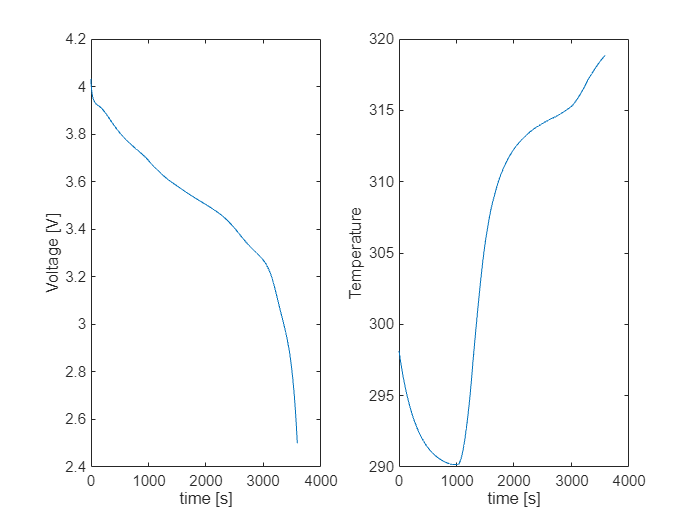

subplot(1,2,1)
plot(result.time, sim_voltage)

xlabel('time [s]'); ylabel('Voltage [V]')

subplot(1,2,2)
plot(result.time, temperature)
xlabel('time [s]'); ylabel('Temperature')

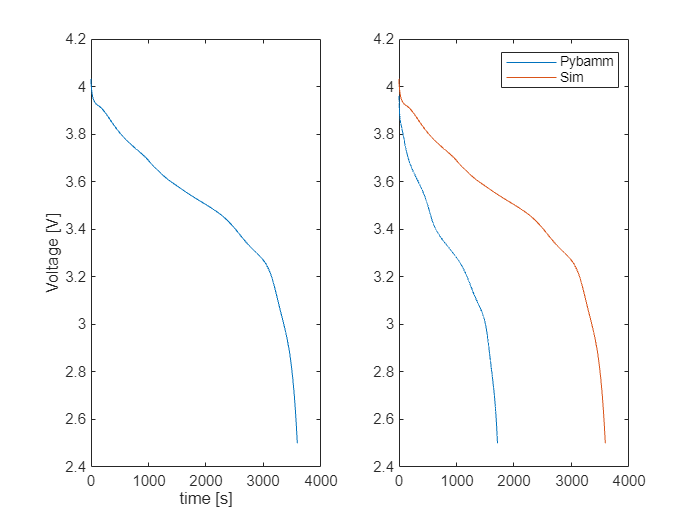

load('Discharge_2C.mat');
plot(time, voltage)
hold on
plot(result.time, sim_voltage)
hold off
legend('Pybamm','Sim')